# Maximizing Solar Panel Output for a Fixed Area

In this project, you will use MATLAB to formulate and solve an optimization problem: Given a fixed area, determine the optimal tilt angle and aspect ratio of a solar panel to maximize the total energy output.

Use this Live Script as a template to get started on your project solution. You may include helper functions at the bottom of this document or as separate files. For a tutorial on how to use Live Scripts, check out this [video](https://www.youtube.com/watch?v=hUXTyPYRidM).

**Suggested Tasks**

- Define the objective function in MATLAB (the energy function).

- Use a [problem-based optimization workflow](https://www.mathworks.com/help/releases/R2026a/optim/ug/problem-based-workflow.html?searchPort=57359) to find the values of θ and r that maximize the energy output. Constrain the values: 0 ≤ θ ≤ 90 and 0.5 ≤ r ≤ 4

- Plot the objective function using `meshgrid` and [`surf`](https://www.mathworks.com/help/matlab/ref/surf.html) to visualize E(θ, r) as a 3D surface plot. Then, print the optimal angle, ratio, and corresponding energy output.

## Break Down the Problem

In the space below, define the problem statement:

List the requirements, constraints, and success criteria for the project:

What is your proposed solution?

List the steps you will need to take to achieve your proposed solution:

What challenges do you face in the process of achieving the solution?

## Task 1: Define the Objective Function

The energy function is the objective function for this optimization problem. It calculates how much energy a solar panel produces based on its tilt angle (theta) and aspect ratio (r). Check the Project Description for the energy formula and parameter definitions and use the image below as a guide:

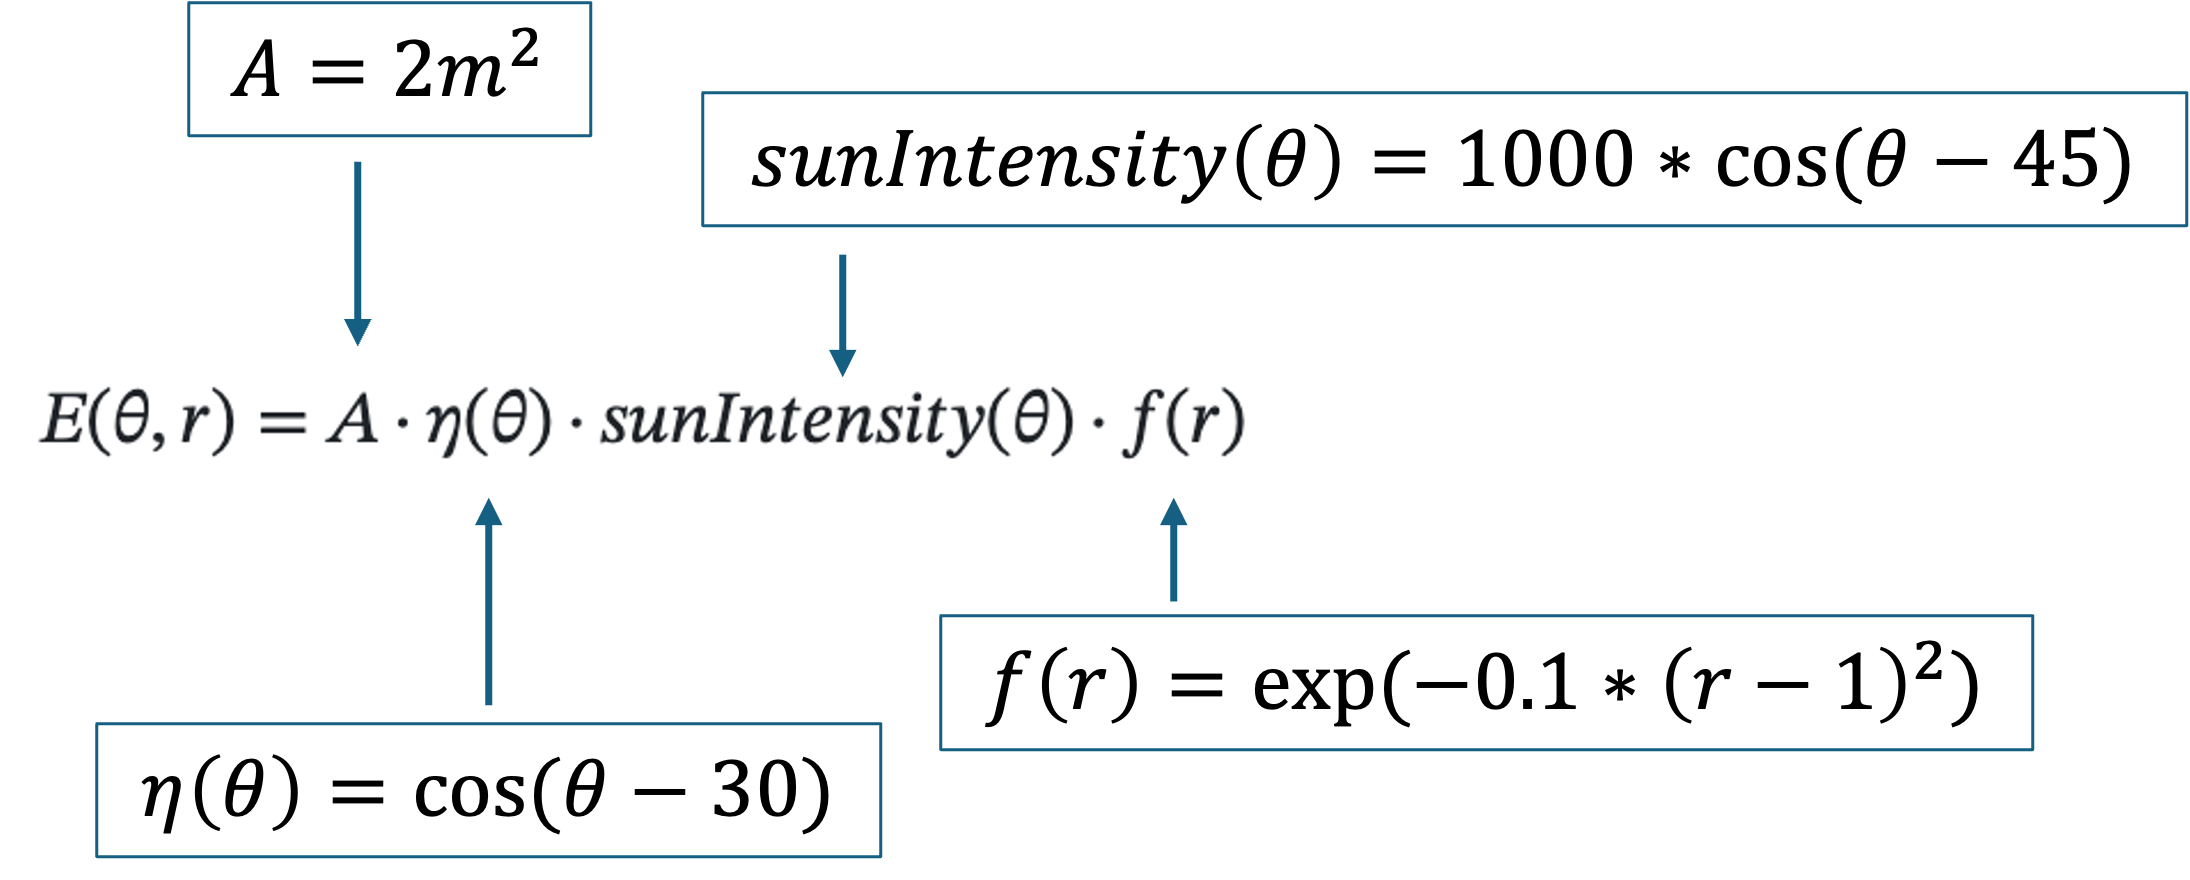

% Insert your code in the spaces provided (or make use of helper functions and indicate where
% they can be found). Ensure your code is well-documented.

% Your energy function should output energy units and take as inputs tilt
% angle (theta) and aspect ratio (r). Using the intermediary steps can help
% simplify how you define E.

% Step 1: Define A (panel area in m^2)

A = 2;

% Step 2: Define nu (efficiency function based on tilt angle)

nu = @(theta) cosd(theta - 30);

% Step 3: Define sunIntensity (sunPractical next steps would be to improve the model by transitioning to real world factors like solar irradiance and weather conditions for a specific area the panel would be installed at. This model could also add panel azimuth which is the direction the panel is facing, inverter efficiency, wiring losses, or installation related losses. During installation there is a drop in efficiency caused by light induced degradation, when the solar cells first meet the solar rays. Long term effects like long term degradation, dust accumulation, and aging should be included. Test different starting points 
confirming the optimum angle. Also the hedicted angle can be evaluated by making a physical prototype for real world values or compare it to 
existing solar panel data taken from various locations.
tht variation with tilt)

sunIntensity = @(theta) 1000 .* cosd(theta - 45);

% Step 4: Define fr (shape efficiency factor based on aspect ratio)

fr = @(r) exp(-0.1 .* (r - 1).^2);

% Step 5: Calculate E (total energy output)

E = @(theta, r)  A .* nu(theta) .* sunIntensity(theta) .* fr(r);



## Task 2: Implement the Optimization Function

Use MATLAB's Optimization Toolbox to find the optimal tilt angle and aspect ratio that MAXIMIZE energy output. This MATLAB [doc page](https://www.mathworks.com/help/optim/ug/problem-based-workflow.html) will be helpful.

% Insert your code in the spaces provided (or make use of helper functions and indicate where
% they can be found). Ensure your code is well-documented. The intermediary
% steps below take you through a problem-based optimization workflow.

% Step 1. Create the optimization problem. We're telling MATLAB: "We want to MAXIMIZE something."
% That "something" will be energy.

prob = optimproblem(ObjectiveSense = "maximize");

% Step 2. Define the optimization variables we can change in the problem
% These are the values MATLAB will try to optimize:
% - theta (tilt angle), must stay between 0 and 90 degrees
% - r (aspect ratio), must stay between 0.5 and 4

theta = optimvar( "theta", LowerBound = 0, UpperBound = 90);

r = optimvar( "r", LowerBound = 0.5, UpperBound = 4);

% Step 3. Turn our energy function into an optimization problem MATLAB can work
% with.
% This step wraps our energy function so MATLAB can plug in different
% theta and r values while solving the problem.
% note: we're optimizing our energy function, so we should try to convert
% that function into an optimization expression

energyOpt = fcn2optimexpr(E, theta, r);

% Step 4. Tell MATLAB what we want to maximize
% We set our energy formula as the "objective" of the problem
% (this is what we want the solver to maximize)

prob.Objective = energyOpt;

% Step 5. Give MATLAB a starting point to begin the search
% Optimization needs a guess to start from:
     % Start searching from a tilt angle of ? degrees
     % Start searching from an aspect ratio of ?

start.theta = 45;

start.r = 1;

% Step 6. Now solve the problem!
% Hint: look for a Optimization Toolbox function meant to solve
% expressions. Store the outputs for plotting purposes later on.

[sol, maximizeEnergy] = solve(prob, start);


Solving problem using fmincon.

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


## Task 3: Output the Results

Use the appropriate plotting function to plot E(θ, r) and visualize the energy surface. Print the optimal tilt angle and aspect ratio, and corresponding energy output.

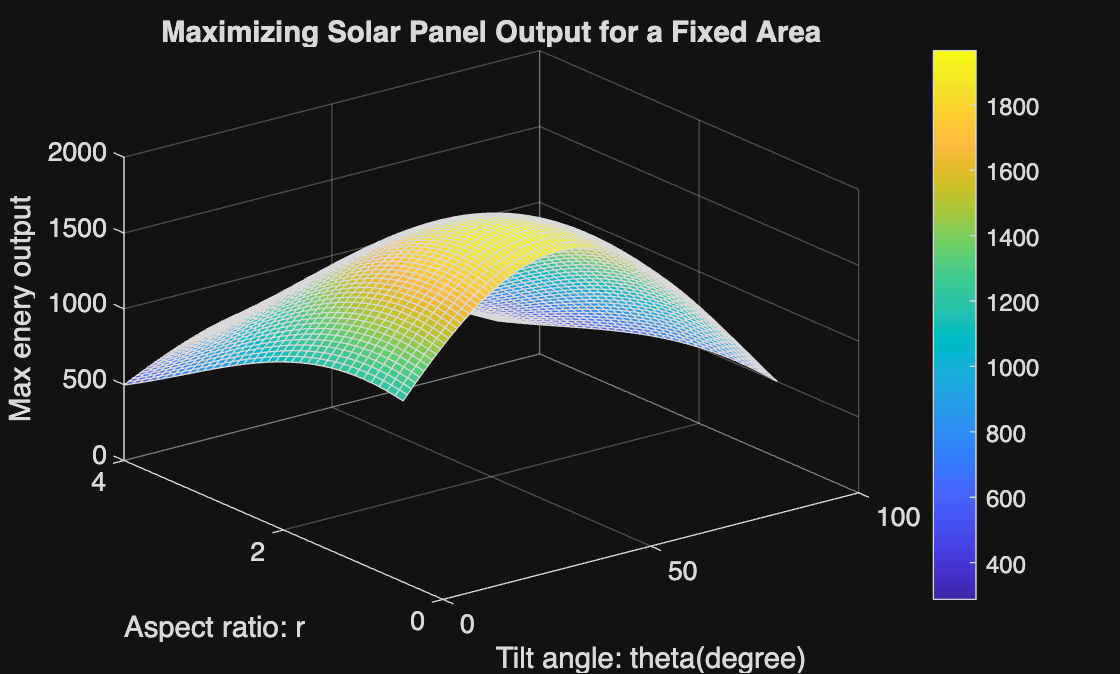

% Insert your code in the spaces provided (or make use of helper functions and indicate where
% they can be found). Ensure your code is well-documented. The intermediary
% steps below will guide you through creating a 3D surface plot.

% Step 1: Make a bunch of points for the x and y axis meshgrid
% The step for the angle is 1, the step for ratio is 0.1
% Hint: keep theta and r within the constraints specified in the problem

thetaAngles = 0: 1: 90;

rValues = 0.5: 0.1: 4;

[thetaGrid, rGrid] = meshgrid(thetaAngles, rValues);

% Step 2: Calculate energy for every point on the meshgrid using element-wise operations

EGrid = E(thetaGrid, rGrid);

% Step 3: Draw the 3d graph using the "surf" function

figure;

surf( thetaGrid, rGrid, EGrid);

% Step 4: Label everything on the surf plot (title, axes, etc)

xlabel("Tilt angle: theta(degree)");

ylabel("Aspect ratio: r");

zlabel("Max enery output");

title("Maximizing Solar Panel Output for a Fixed Area");

grid on;

colorbar;


% Step 5: Print the optimal tilt angle and aspect ratio, and corresponding
% energy output to the command window

fprintf("Optimal Tilt Angle: %.3f degrees\n", sol.theta);

Optimal Tilt Angle: 37.500 degrees



fprintf("Optimal Shape (Aspect Ratio): %.3f\n", sol.r);

Optimal Shape (Aspect Ratio): 1.000



fprintf("Maximum Energy Output: %.3f Simplified Arbitrary Units\n", maximizeEnergy);

Maximum Energy Output: 1965.926 Simplified Arbitrary Units


## Interpretation of Results

Summarize your findings by interpreting their physical/engineering meaning:

The optimal tilt angle was found to be 37.5 degrees and the optimal shape or aspect ratio was found to be 1. This produced a maximum energy output of 1965.926 simplified arbitrary units. With the tilt angle there are two variables contributing to the optimal angle. For tilt efficiency, nu the best angle is 30 degrees. For the highest sun intensity its at 45 degrees. The aspect ratio at 1 is the square 2 m^2, the square provides the most efficient panel.

What are some limitations of your work?

This model does not simulate the real world conditions like the elements for example location, time of day, what season its in, if there are clouds, shady spots from other panels or other blockages, temperature, dust, or inverter efficiency when converting DC to AC. The shape efficiency equation fr is a geometric approximation rather than based on physics, environment, or material. The output is in simplified arbitrary units rather than real world units like watts per square meter (W/m²). This optimization is determined only by the equation, assumptions, constraints in the model.

What are practical next steps?

Practical next steps would be to improve the model by transitioning to real world factors like solar irradiance and weather conditions for a specific area the panel would be installed at. This model could also add panel azimuth which is the direction the panel is facing, inverter efficiency, wiring losses, or installation related losses. When the solar cells first meet the solar rays there is a drop in efficiency caused by light induced degradation. Long term effects like long term degradation, dust accumulation, and aging should be included. Test different starting points confirming the optimum angle. Also the predicted angle can be evaluated by making a physical prototype for real world values or compare it to existing solar panel data taken from various locations.